# Separation of Variables 

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

When solving first-order ordinary differential equations, a good first approach is check whether the equation is separable. This is because **separation of variables** is typically the most straightforward analytical method to solve a differential equation. In this script, we'll learn and practice how to use this method, using an application of logistic population growth to help us do so.

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Separation of Variables

### Method of Separation of Variables

What makes an equation separable? In a first-order differential equation where $x$ is the independent variable and $y$ is the dependent variable, the equation is separable if it can be written in the following form.

 
$$\frac{dy}{dx} = f(x) \cdot g(y)
$$


Moving all of the $x$ terms to one side and all of the $y$ terms to the other, we get:


$$\frac{1}{g(y)} \cdot dy = f(x) \cdot dx
$$


In other words, a separable equation is an equation where all of the $y$ terms and all of the $x$ terms can be "separated" on different sides of the equation.

Once we have the $x$ and $y$ terms separated, we can take the integral of both sides of the equation, and then solve for $y$.

  You may be asking, why are we able to separate $dy$ and $dx$? Isn't this derivative term just a single term?

Technically that's correct. The derivative term $y' = \frac{dy}{dx}$ is just a single term and not a fraction that we can pull apart. 

When separating variables, we are actually taking the integral of both sides with respect to $x$.


$$g(y) \cdot y' = f(x)
$$



$$\int{g(y) \cdot y'} \; dx = \int f(x) \; dx
$$


Using "u-substitution", we can rewrite the left-hand side, so that the equation looks like the following.


$$\int{g(y)} \; dy = \int f(x) \; dx
$$


Therefore, even if not technically correct, separating $dy$ and $dx$ before taking the integral of both sides is convenient shorthand, so feel free to use it when solving using separation of variables.

### Classify Separable Equations

For each of the following differential equations, select whether or not it is separable. 

Remember that when $x$ is the independent variable and $y$ is the dependent variable, $y'$ is equivalent to $\frac{dy}{dx}$.

  **Exercise 1.** Consider the following equation:


$$\frac{dy}{dx} = 3x^2 \cdot y$$
 

CheckExercise1("");
 

  **Exercise 2.** Consider the following equation. 


$$xy' = e^x \cdot y^2$$


CheckExercise2("");
 

  **Exercise 3.** Consider the following equation:


$$\frac{dy}{dx}= 3y + x$$


CheckExercise3("");
 

### Example of Separation of Variables

Consider the following differential equation and initial condition.


$$ y' = y \cdot \cos(t)$$
     
$$y(0) = 3$$


First, remember that we can rewrite $y'$ as $\frac{dy}{dt}$.


$$\frac{dy}{dt} = y \cdot \cos(t)$$


Next, let's separable the variables so that all $y$ terms are on one side, and all $t$ terms are on another.


$$\frac{1}{y} \; dy = \cos(t) \;dt$$


Next, let's take the integral of both sides of the equation, and solve for $y$.


$$\int \frac{1}{y} \; dy = \int \cos(t) \; dt$$



$$\ln(y) = \sin(t) + C$$



$$y = e^{\sin(t) + C}$$



$$y = e^{\sin(t)} \cdot e^C$$


Simplifying $e^C$ to $C$, because they are both just arbitrary constants, we get our **general solution.**


$$y = Ce^{\sin(t)}$$


Applying the initial condition $y(0) = 3$ allows us to find the **particular solution.**


$$3 = Ce^{\sin(0)}$$
     
$$3 = Ce^{0}$$
     
$$3 = C$$



$$y = 3e^{\sin(t)}$$


### Practice with Separation of Variables

Next, let's practice applying this method to solve a new differential equation. 

  Some important things to keep in mind when typing math expressions into the edit fields for the exercises:

- Make sure that you use parentheses carefully.

- When multiplying values, explicitly use the multiplication symbol. Instead of writing "`2t"`, write `"2*t"`.

- `"log(x)"` in MATLAB is equivalent to `"ln(x)"` in math class.

- `"exp(x)"` in MATLAB is equivalent to `"e^x"` in math class.

**Exercise 4.**

Consider the following differential equation:


$$\frac{y'}{x} = e^x \cdot y^2$$


 a. Find the general solution. Note: use $C$ for the constant term.

syms x C

Check4a( 0);
 

Show4a(false);

 b. Find the particular solution, given the initial condition $y(0) = -1$.

syms x

Check4b( 0);
 

Show4b(false);

##  Application: Logistic Population Growth

An important application of differential equations is in the context of population growth for a species. The logistic growth model assumes that there is a maximum sustainable population of a species, or "carrying capacity", that an environment can handle. 

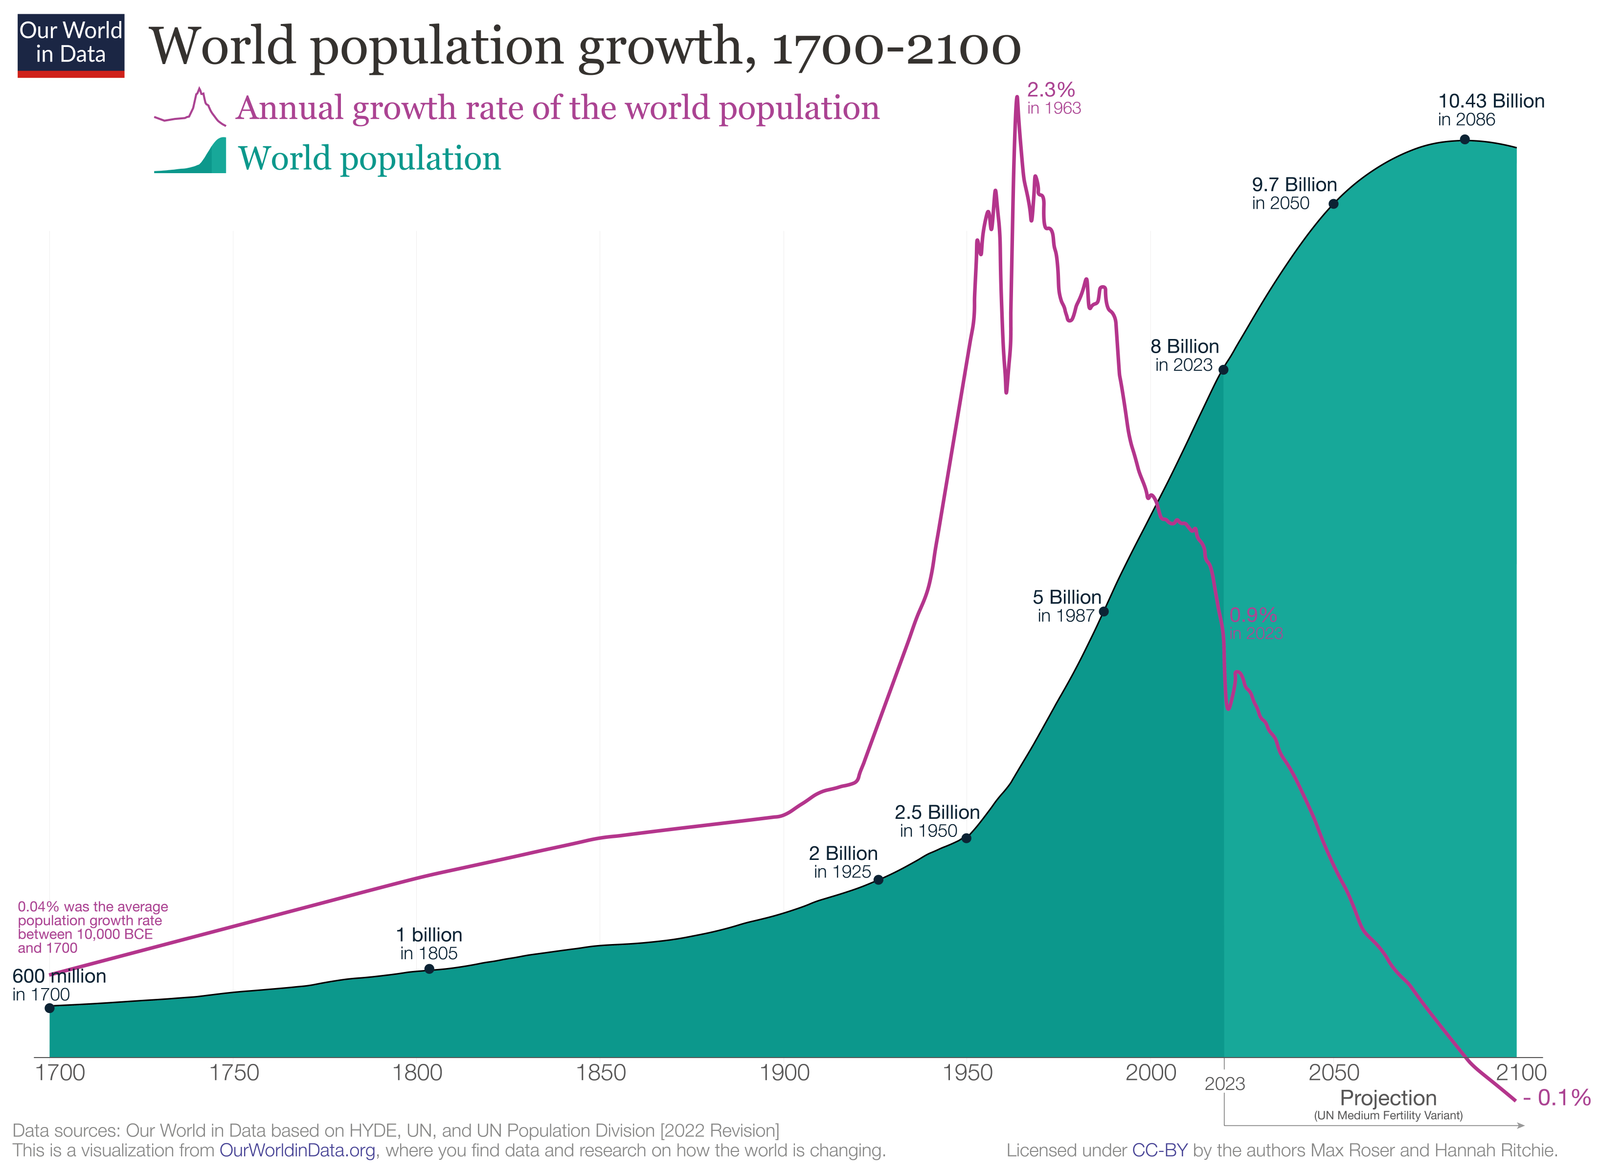

[Credit: Max Roser and Hannah Ritchie, CC BY 4.0](https://commons.wikimedia.org/wiki/File:World_population_growth,_1700-2100,_2022_revision.png)

The first-order differential equation for the logistic growth model looks like this.


$$\frac{dP}{dt} = rP (1 - \frac{P}{K})$$


Let's break down each of these variables:

- $P$ represents the population of the species, and so it's our **dependent variable**

- $t$ represents the elapsed time, and so it's our **independent variable**

- $K$represents the carrying capacity, or maximum population

- $r$ represents the growth rate per year- a value of 0.1 means a 10% growth rate per year

### Human Population

**Exercise 5.** 

Let's use this logistic population growth model to try to model human population growth! Our goal is to predict what the human population will be in 2050.

- In order to simplify our calculations, let's assume that 1 unit of $P$ represents 1 million people.

- Additionally, let's assume that 1 unit of $t$ represents 1 year.

- The population is expected to peak at approximately 10.5 billion people, so let's assume this number to be our carrying capacity.

- Let's assume a growth rate of 5% per year.

 a. What is the differential equation that models this scenario?

syms P t
Check5a( 0);
 

Show5a(false);

 b. Separate the variables. (Hint: make use of partial fraction decomposition to split up the $P$ term into two fractions that will be easier to integrate.)

syms P t
Check5bDP( 0);
 

syms P t
Check5bDT( 0);
 

Show5b(false);

 c. Integrate both sides of the equation, and solve for $P$. Note: use $C$ for the constant term.

syms t C
Check5c( 0);
 

Show5c(false);

 d. As of 2024, the human population is approximately 8.2 billion people, and let $t = 0$ represent 2024. Use this to solve for the constant term $C$and find an exact expression for $P$. (Hint: Multiply the numerator and denominator of $P$ by 23 to simplify at the end).

syms t
Check5dC( 0);
 

syms t
Check5dP( 0);
 

Show5d(false);

 e. Finally, what does the our solution predict the population will be in 2050? Round to the nearest million people.

syms t
Check5e(0);
 

Show5e(false);

**Exercise 6. **

Next, let's generalize the solution for any value of $K$, $r$, and $P_0$.

 a. What is the general solution to the logistic growth model differential equation?

syms K C r t
Check6a( 0);
 

Show6a(false);

 b. What is the particular solution to the logistic growth model differential equation, given $P_0$? Solve for the constant term $C$and find an exact expression for $P$.

syms K C r t P0
Check6bC( 0);
 

syms K r t P0
Check6bP( 0);
 

Show6b(false);

### **Visualize the Effect of Parameters**

   Explore how changes to various parameters impact the model!

Set values for $K$, $r$, and $P_0$:

kVal = 10500;
rVal =0.05;
P0Val = 8200;

Set the range of time values you would like to see in the graph: 

tRange =[-100 50];

Specify a specific time where you would like to see the predicted population.

tVal = 26;

Click below to run (or re-run) the graph!

 
ShowLogisticGrowthEquationAndGraph(P0Val, kVal, rVal, tRange, tVal)

## Further Exploration

You can learn how to calculate symbolic solutions to ODEs in [CheckYourWork](matlab:open('.\CheckYourWork.mlx')). 

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function CheckExercise1(answer)
    if answer == ""
        disp("Please select an answer.")
    elseif answer == "separable"
        disp("Correct! This can be rewritten as:")
        displayFormula("1/y * dy == 3*x^2 * dx")
    else
        disp("Incorect- check again to see if all of the x and y terms can be separated.")
    end
end

function CheckExercise2(answer)
    if answer == ""
        disp("Please select an answer.")
    elseif answer == "separable"
        disp("Correct! Using y' = dy/dx, this can be rewritten as:")
        displayFormula("1/y^2 * dy == (e^x / x) * dx")
    else
        disp("Incorrect- check again to see if all of the x and y terms can be separated.")
    end
end

function CheckExercise3(answer)
    if answer == ""
        disp("Please select an answer.")
    elseif answer == "separable"
        disp("Incorrect- check again to see if all of the x and y terms can be separated.")
    else
        disp("Correct! There is no way to separate the x and y terms in this equation, so it is not separable.")
    end
end


% check exercise 4
function Check4a(expression)
    syms x C
    correctExp = -1/((exp(x)*(x - 1)) + C);
    hint = "Incorrect- try rechecking your calculations, or see below for an explanation.";
    CheckExpression(expression, correctExp, hint);
end

function Check4b(expression)
    syms x
    correctExp = -1/((exp(x)*(x - 1)) + 2);
    hint = "Incorrect- try plugging the initial condition into the equation from part (a) to solve for C.";
    CheckExpression(expression, correctExp, hint);
end

% check exercise 5
function Check5a(expression)
    syms P t
    correctExp = 0.05*P*((10500 - P)/10500);
    hint = "Incorrect- recheck the values you are plugging in to the logistic growth model equation.";
    CheckExpression(expression, correctExp, hint);
end

function Check5bDP(expression)
    syms P t
    correctExp = (1/P) + 1/(10500 - P);
    hint = "Incorrect- try rechecking your calculations, or see below for an explanation.";
    CheckExpression(expression, correctExp, hint);
end

function Check5bDT(expression)
    syms P t
    correctExp = 0.05;
    hint = "Incorrect- move all t terms and any constants to this side of the equation.";
    CheckExpression(expression, correctExp, hint);
end

function Check5c(expression)
    syms t C
    correctExp = (10500 * C * (exp(0.05*t))) / (1 + C * exp(0.05*t));
    hint = "Incorrect- integrate both sides, then rearrange to find an expression for P solely dependent on t and a constant term C.";
    CheckExpression(expression, correctExp, hint);
end

function Check5dC(expression)
    syms t
    correctExp = 82/23;
    hint = "Incorrect- remember that 1 unit of P represents 1 million people, so try plugging P(0) = 8200 " + ...
        "into the equation from part (c) to solve for C.";
    CheckExpression(expression, correctExp, hint);
end

function Check5dP(expression)
    syms t
    correctExp = (861000*(exp(0.05*t))) / (23 + (82*(exp(0.05*t))));
    hint = "Incorrect- try plugging the value we found for C back into the equation from part (c).";
    CheckExpression(expression, correctExp, hint);
end

function Check5e(answer)
    if answer <= 0 || floor(answer) ~= answer
        disp("Please enter a positive integer.")
    elseif answer == 9754000000
        disp("Correct! See below for a detailed explanation.")
    else
        disp("Incorrect- try plugging in t = 2050-2024 = 26 into our solution from part (d).")
    end
end

% check exercise 6
function Check6a(expression)
    syms K C r t
    correctExp = (K * C * (exp(r*t))) / (1 + C*(exp(r*t)));
    hint = "Incorrect- try starting with our general solution from 5c, and generalizing for any value of K and r.";
    CheckExpression(expression, correctExp, hint);
end

function Check6bC(expression)
    syms K P0
    correctExp = P0 / (K - P0);
    hint = "Incorrect- try going back to exercise 5d, and generalize how we solved for C";
    CheckExpression(expression, correctExp, hint);
end

function Check6bP(expression)
    syms K r t P0
    correctExp = (K * P0 * (exp(r*t))) / (K - P0 + (P0 * (exp(r*t))));
    hint = "Incorrect- try plugging our value of C into our expression from part (a).";
    CheckExpression(expression, correctExp, hint);
end

% helper function to check expressions
function CheckExpression(exp, correctExp, hint)
    if isAlways(exp == correctExp, Unknown="false")
        disp("Correct! See below for a detailed explanation.")
    elseif exp == 0
        disp("Please enter a nonzero expression.")
    else
        disp(hint)
    end
end

function Show4a(checked)
    if checked
        displayFormula(["'We start by separating variables, to get:'"; ...
            "1/y^2 * dy ==  e^x * x * dx"; ...
            "'Taking the integral of both sides, using integration by parts for the right hand side, we get:'"; ...
            "int(1/y^2) ==  int(e^x * x)"; ...
            "-1/y ==  e^x * (x - 1) + C"; ...
            "'Finally, solving for y, we get:'"; ...
            "y == -1/(e^x * (x - 1) + C)"]);
    end
end

function Show4b(checked)
    if checked
        displayFormula(["'We start with out general solution:'"; ...
            "y == -1/(e^x * (x - 1) + C)"; ...
            "'Plugging in x = 0 and y = -1, we get:'"; ...
            "-1 == -1/(e^0 * (0 - 1) + C)"; ...
            "-1 == -1/(C - 1)"; ...
            "C = 2"; ...
            "'Therefore, the particular solution is:'"; ...
            "y == -1/(e^x * (x - 1) + 2)"]);
    end
end

function Show5a(checked)
    if checked
        displayFormula(["'We start with our logistic growth model:'"; ...
            "dP/dt = rP(1 - P/K)"; ...
            "'Plugging in K = 10500 and r = 0.05, we get:'"; ...
            "dP/dt = 0.05*P(1 - P/10500)"; ...
            "'Rewriting the fraction on the right hand side to make it easier for us later, we get:'"; ...
            "dP/dt = 0.05*P((10500 - P)/10500)"])
    end
end

function Show5b(checked)
    if checked
        displayFormula(["'We start with our answer from part (a):'"; ...
            "dP/dt = 0.05*P((10500 - P)/10500)"; ...
            "'Separating all P terms to the LHS and t terms to the RHS, we get:'"; ...
            "10500/(P*(10500-P))*dP = 0.05*dt"; ...
            "' '"; ...
            "'Using partial fraction decomposition, we have:'"; ...
            "10500/(P*(10500-P)) = ((10500-P)/(P*(10500-P)) + P/(P*(10500-P)))"; ...
            "10500/(P*(10500-P)) = (1/P) + (1/(10500-P))"; ...
            "' '"; ...
            "'Therefore, we have:'"; ...
            "((1/P) + (1/(10500-P)))*dP = 0.05*dt"])
    end
end

function Show5c(checked)
    if checked
        displayFormula(["'We start with our answer from part (b):'"; ...
            "((1/P) + (1/(10500-P)))*dP = 0.05*dt"; ...
            "' '"; ...
            "'Take the integral of both sides:'"; ...
            "int((1/P) + (1/(10500-P))) = int(0.05, t)"; ...
            "int(1/P) + int(1/(10500-P)) = int(0.05, t)"; ...
            "ln(P) + (-ln(10500-P)) = 0.05*t + C"; ...
            "' '"; ...
            "'Use log rules to rewrite the left hand side:'"; ...
            "ln(P/(10500-P)) = 0.05*t + C"; ...
            "P/(10500-P) = e^(0.05*t + C)"; ...
            "' '"; ...
            "'Rewrite the arbitrary constant:'"; ...
            "P/(10500-P) = e^(0.05*t)*e^C"; ...
            "P/(10500-P) = C * e^(0.05*t)"; ...
            "' '"; ...
            "'Solve for P:'"; ...
            "P = (10500-P) * C * e^(0.05*t)"; ...
            "P = (10500 * C * e^(0.05*t)) - (P * C * e^(0.05*t))"; ...
            "P + (P * C * e^(0.05*t)) = (10500 * C * e^(0.05*t))"; ...
            "P * (1 + C * e^(0.05*t)) = (10500 * C * e^(0.05*t))"; ...
            "P = (10500 * C * e^(0.05*t))/(1 + C * e^(0.05*t))"])
    end
end

function Show5d(checked)
    if checked
        displayFormula(["'Let's use the following equation that we derived in part (d) to solve for the arbitrary constant C.'"; ...
            "P/(10500-P) = C * e^(0.05*t)"; ...
            "' '"; ...
            "'Plugging in t = 0 and P = 8200, we have:'"; ...
            "8200/(10500-8200) = C * e^(0.05*0)"; ...
            "C = 8200/(10500-8200)"; ...
            "C = 8200/2300"; ...
            "C = 82/23"; ...
            "' '"; ...
            "'Finally, we can plug in this value of C into the general solution from part (d), and simplify:'"; ...
            "P = (10500 * C * e^(0.05*t))/(1 + C * e^(0.05*t))"; ...
            "P = (10500 * (82/23) * e^(0.05*t))/(1 + (82/23) * e^(0.05*t))"; ...
            "P = ((861000/23) * e^(0.05*t))/((23 + (82 * e^(0.05*t)))/23)"; ...
            "P = (861000 * e^(0.05*t))/(23 + (82 * e^(0.05*t)))"]);
    end
end

function Show5e(checked)
    if checked
        displayFormula(["'Because we are taking 2024 to be t=0, 2050 is t=26.'"; ...
            "'Plugging t=26 into our particular solution from part (d), we get:'"; ...
            "P = (861000 * e^(0.05*t))/(23 + (82 * e^(0.05*t)))"; ...
            "P = 9754.36"; ...
            "'Because 1 unit of P represents 1 million people, we have that the population in 2050 is predicted to be'"; ...
            "'approximately 9,754,000,000, or 9.7 billion people.'"]);
    end
end

function Show6a(checked)
    if checked
        displayFormula(["'Let's start with our general solution from question 5:'"; ...
            "P = (10500 * C * e^(0.05*t))/(1 + C * e^(0.05*t))"; ...
            "'Given that in this example we had K = 10500, and r = 0.05, we can generalize the solution as follows:'"; ...
            "P = (K * C * e^(r*t))/(1 + C * e^(r*t))"]);
    end
end

function Show6b(checked)
    if checked
        displayFormula(["'Let's start with the equation we used to solve for the arbitary constant C in question 5:'"; ...
            "C = 8200/(10500-8200)"; ...
            "'Given that in this example we had K = 10500 and P0 = 8200, we can generalize this as follows:'";
            "C = P_0/(K-P_0)"; ...
            "'Plugging C into the general solution from part (a), we get:'"; ...
            "P = (K * C * e^(r*t))/(1 + C * e^(r*t))"; ...
            "P = (K * (P_0/(K-P_0)) * e^(r*t))/(1 + (P_0/(K-P_0)) * e^(r*t))"; ...
            "P = (K * P_0 * e^(r*t)/(K-P_0))/((K - P_0 + P_0 * e^(r*t))/(K-P_0))"; ...
            "P = (K * P_0 * e^(r*t))/((K - P_0 + (P_0 * e^(r*t))))"]);
    end
end

function ShowLogisticGrowthEquationAndGraph(P0Val, kVal, rVal, tRange, tVal)
    % display generic formula
    syms P(t) P0 k r;
    rhs = (k*P0*exp(r*t))/((k - P0) + P0*exp(r*t));
    f = P(t) == rhs;
    displayFormula(char(f));

    % display formula with values plugged in
    disp("Plugging in these custom parameters, we get:")
    rhs_sub = subs(rhs, [P0, k, r], [P0Val, kVal, rVal]);
    f_sub = P(t) == rhs_sub;
    displayFormula(char(f_sub));

    % plot line
    disp("Here's a plot of the solution:")
    fplot(rhs_sub, [tRange(1) tRange(2)])
    hold on

    % add point at t = 0
    plot(0, P0Val, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
    P0label = sprintf('P(0) = %d', P0Val);
    text(0, P0Val, P0label, 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left');

    % add point at t = tVal
    if tVal ~= 0
        Pt = subs(rhs_sub, t, tVal);
        plot(tVal, Pt, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
        Ptlabel = sprintf('P(%d) = %d', tVal, Pt);
        text(tVal, Pt, Ptlabel, 'VerticalAlignment', 'top', 'HorizontalAlignment', 'left');
    end

    % add title and labels
    title('Logistic Population Growth');
    xlabel('Time');
    ylabel('Population');
    hold off
end

function problem = GenerateSeparableEquation()
syms x y f(x) g(y)

end